# Tilt 

-60 deg to 60 deg with 21 diverging waves inbetween 

clear; close all; clc;
% parameters we want to change (comment out what you want to change and
% change it in the for loops
tlt = 60 % tilt we want

tlt = 60

dw = 21 % amount of diverging waves we want

dw = 21

%dwn = 4 % diverging wave number
D2R = 60 %the degree wide we want

D2R = 60

fov = 120 % degree of field of view

fov = 120

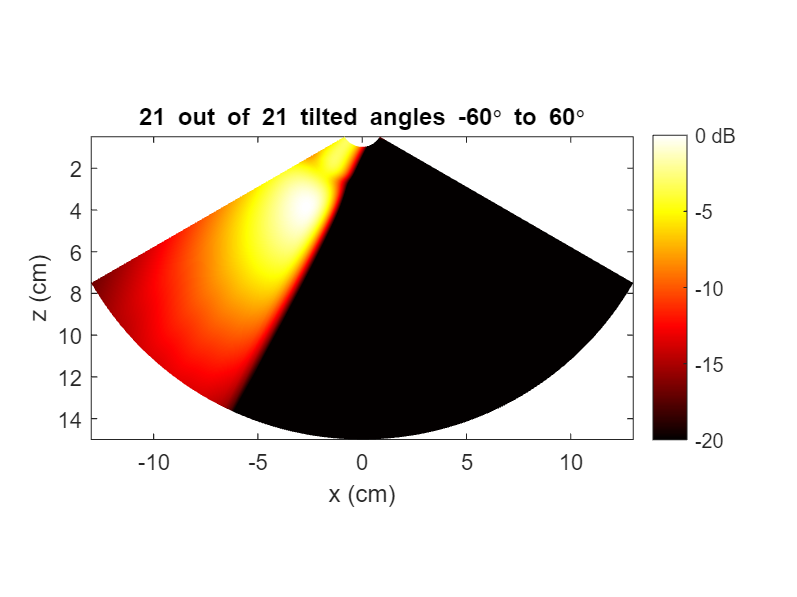


for dwn = 1:21
%% code from website with parameters put in 
    param = getparam('P4-2v');
    param.TXapodization = cos(linspace(-1,1,64)*pi/2);
    tilt = deg2rad(linspace(-1*tlt,tlt,dw)); % tilt angles in rad
    txdel = cell(dw,1); % this cell will contain the transmit delays
    
        for k = 1:dw
            txdel{k} = txdelay(param,tilt(k),deg2rad(D2R));
        end
            % stem(txdel{1}*1e6)
            % xlabel('Element number')
            % ylabel('Delays (\mus)')
            % title('TX delays for a 60{\circ}-wide -20{\circ}-tilted wave')
            % axis tight square
    
    
    [xi,zi] = impolgrid([100 100],15e-2,deg2rad(fov),param);
    option.WaitBar = false;
    P = pfield(xi,0*xi,zi,txdel{dwn},param,option);
        pcolor(xi*1e2,zi*1e2,20*log10(P/max(P(:))))
        shading interp
        xlabel('x (cm)')
        ylabel('z (cm)')
        title([num2str(dwn) ' out of 21 tilted angles -60{\circ} to 60{\circ}'])
        axis equal ij tight
        caxis([-20 0]) % dynamic range = [-20,0] dB
        cb = colorbar;
        cb.YTickLabel{end} = '0 dB';
        colormap(hot)
   saveas(gcf,['Tilt ' num2str(dwn) '.jpg']) 
end

# Width of Wave

with tilt of 0 deg 

changing width of wave from 10 deg to 120 deg with intervals of 10 deg.

clear; close all; clc;
% parameters we want to change 
tlt = 20 % tilt we want

tlt = 20

dw = 7 % amount of diverging waves we want

dw = 7

dwn = 4 % diverging wave number

dwn = 4

% D2R = 30 %the degree wide we want
fov = 120 % degree of field of view

fov = 120

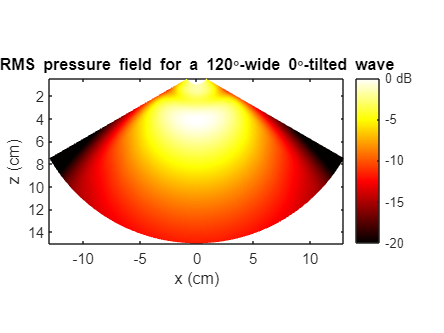


for D2R = 10:10:120
%% code from website with parameters put in 
    param = getparam('P4-2v');
    param.TXapodization = cos(linspace(-1,1,64)*pi/2);
    tilt = deg2rad(linspace(-1*tlt,tlt,dw)); % tilt angles in rad
    txdel = cell(dw,1); % this cell will contain the transmit delays
    
        for k = 1:dw
            txdel{k} = txdelay(param,tilt(k),deg2rad(D2R));
        end
            % stem(txdel{1}*1e6)
            % xlabel('Element number')
            % ylabel('Delays (\mus)')
            % title('TX delays for a 60{\circ}-wide -20{\circ}-tilted wave')
            % axis tight square
    
    
    [xi,zi] = impolgrid([100 100],15e-2,deg2rad(fov),param);
    option.WaitBar = false;
    P = pfield(xi,0*xi,zi,txdel{dwn},param,option);
        pcolor(xi*1e2,zi*1e2,20*log10(P/max(P(:))))
        shading interp
        xlabel('x (cm)')
        ylabel('z (cm)')
        title(['RMS pressure field for a ' num2str(D2R) '{\circ}' ...
            '-wide 0{\circ}-tilted wave'])
        axis equal ij tight
        caxis([-20 0]) % dynamic range = [-20,0] dB
        cb = colorbar;
        cb.YTickLabel{end} = '0 dB';
        colormap(hot)
        saveas(gcf,['Pressure field image degree wide ' num2str(D2R) '.jpg'])
end

# Elements

clear; close all; clc;
% parameters we want to change (comment out what you want to change and
% change it in the for loops
tlt = 60 % tilt we want

tlt = 60

dw = 7 % amount of diverging waves we want

dw = 7

dwn = 4 % diverging wave number

dwn = 4

D2R = 60 %the degree wide we want

D2R = 60

fov = 120 % degree of field of view

fov = 120

% ele = 64 % elements within the phased transducer we are using

for ele = 2%[2, 4, 8, 16, 32, 64, 128, 256]
%% code from website with parameters put in 
    param = getparam('P4-2v');
    param.TXapodization = cos(linspace(-1,1,ele)*pi/2);
    tilt = deg2rad(linspace(-1*tlt,tlt,dw)); % tilt angles in rad
    txdel = cell(7,1); % this cell will contain the transmit delays
    
        for k = 1:dw
            txdel{k} = txdelay(param,tilt(k),deg2rad(D2R));
        end
            % stem(txdel{1}*1e6)
            % xlabel('Element number')
            % ylabel('Delays (\mus)')
            % title('TX delays for a 60{\circ}-wide -20{\circ}-tilted wave')
            % axis tight square
    
    
    [xi,zi] = impolgrid([100 100],15e-2,deg2rad(fov),param);
    option.WaitBar = false;
    P = pfield(xi,0*xi,zi,txdel{dwn},param,option);
        pcolor(xi*1e2,zi*1e2,20*log10(P/max(P(:))))
        shading interp
        xlabel('x (cm)')
        ylabel('z (cm)')
        title([num2str(ele) ' elements in transducer'])
        axis equal ij tight
        caxis([-20 0]) % dynamic range = [-20,0] dB
        cb = colorbar;
        cb.YTickLabel{end} = '0 dB';
        colormap(hot)
   saveas(gcf,[num2str(ele) ' elements in transducer.jpg'])
end

Error using assert
PARAM.TXapodization must be of length = (number of elements)

Error in pfield (line 530)
    assert(numel(param.TXapodization)==NumberOfElements,...

## frequency

clear; close all; clc;
% parameters we want to change (comment out what you want to change and
% change it in the for loops
tlt = 60 % tilt we want
dw = 7 % amount of diverging waves we want
dwn = 4 % diverging wave number
D2R = 60 %the degree wide we want
fov = 120 % degree of field of view
ele = 64 % elements within the phased transducer we are using
param = getparam('P4-2v');
for 
%% code from website with parameters put in 
   
    param.TXapodization = cos(linspace(-1,1,ele)*pi/2);
    tilt = deg2rad(linspace(-1*tlt,tlt,dw)); % tilt angles in rad
    txdel = cell(7,1); % this cell will contain the transmit delays
    
        for k = 1:dw
            txdel{k} = txdelay(param,tilt(k),deg2rad(D2R));
        end
            % stem(txdel{1}*1e6)
            % xlabel('Element number')
            % ylabel('Delays (\mus)')
            % title('TX delays for a 60{\circ}-wide -20{\circ}-tilted wave')
            % axis tight square
    
    
    [xi,zi] = impolgrid([100 100],15e-2,deg2rad(fov),param);
    option.WaitBar = false;
    P = pfield(xi,0*xi,zi,txdel{dwn},param,option);
        pcolor(xi*1e2,zi*1e2,20*log10(P/max(P(:))))
        shading interp
        xlabel('x (cm)')
        ylabel('z (cm)')
        title([num2str(ele) ' elements in transducer'])
        axis equal ij tight
        caxis([-20 0]) % dynamic range = [-20,0] dB
        cb = colorbar;
        cb.YTickLabel{end} = '0 dB';
        colormap(hot)
   saveas(gcf,[num2str(ele) ' elements in transducer.jpg'])
end
